# **Assignment 1- Finite Elements Method 1D**

clc
clear
close all

## **Part 1 **

#### **1.1 Boundary Value Problem (BVP)**

% Symbolic variables
syms E A L g real % Constants
syms x real % Position variable
syms u(x) % Displacement function

% Constants definitions
rho = pi^3/L^2;
s = g*pi^4/L^2;
F = A*E*g*pi^2/L;
r = (x/L)^2;

% Distributed force
q = E*(rho*u-s*r);

% Hooke's law (We don't need to define them as symbolic)
epsilon = diff(u,x)

$$epsilon(x) = \frac{\partial }{\partial x}u\left(x\right)$$

sigma = E*epsilon;

% Equilibrium
eq1 = diff(sigma,x)+q==0

$$eq1(x) = \text{E}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)+\text{E}\,\left(\frac{8727491006471547\,u\left(x\right)}{281474976710656\,L^{2}}-\frac{1713638851887625\,g\,x^{2}}{17592186044416\,L^{4}}\right)=0$$


% Boundary conditions
cond1 = u(0) == -g; % Displacement 
du_dx_L = diff(u,x);
cond2 = A*E*subs(du_dx_L,x,L) == F; % Force

% General solution 
u_sol = dsolve(eq1, cond1, cond2);
u_sol_simp = vpa(u_sol,4)

$$u\_sol\_simp = 1.545\,g\,\sin\left(\frac{5.568\,x}{L}\right)-0.7974\,g\,\cos\left(\frac{5.568\,x}{L}\right)-0.2026\,g+\frac{3.142\,g\,x^{2}}{L^{2}}$$

**1.2 Exact Solution**

% Apply numeric values
L_val=1;
g_val=0.01;

% Substitute
u_sol_val=(subs(u_sol,[g L], [g_val, L_val]));
u_sol_val_simp=vpa(u_sol_val,4)

$$u\_sol\_val\_simp = 0.01545\,\sin\left(5.568\,x\right)-0.007974\,\cos\left(5.568\,x\right)+0.03142\,x^{2}-0.002026$$

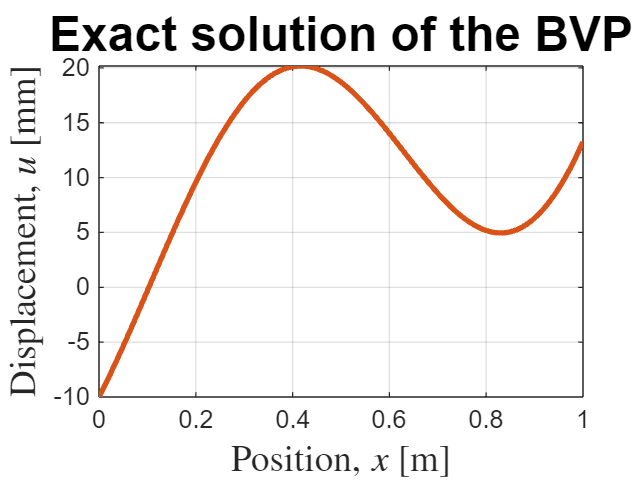


% Plot of the exact solution
colors = lines(8); % Define the colors vector
fplot(u_sol_val_simp*1000, [0 L_val], 'Color', colors(2,:), 'LineWidth',2) % Converted to millimetres: *1000
xlabel('Position, $x$ [m]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Displacement, $u$ [mm]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
grid on
title('Exact solution of the BVP', 'FontSize', 18, 'FontWeight', 'bold');